# E2015

## Opgave 1

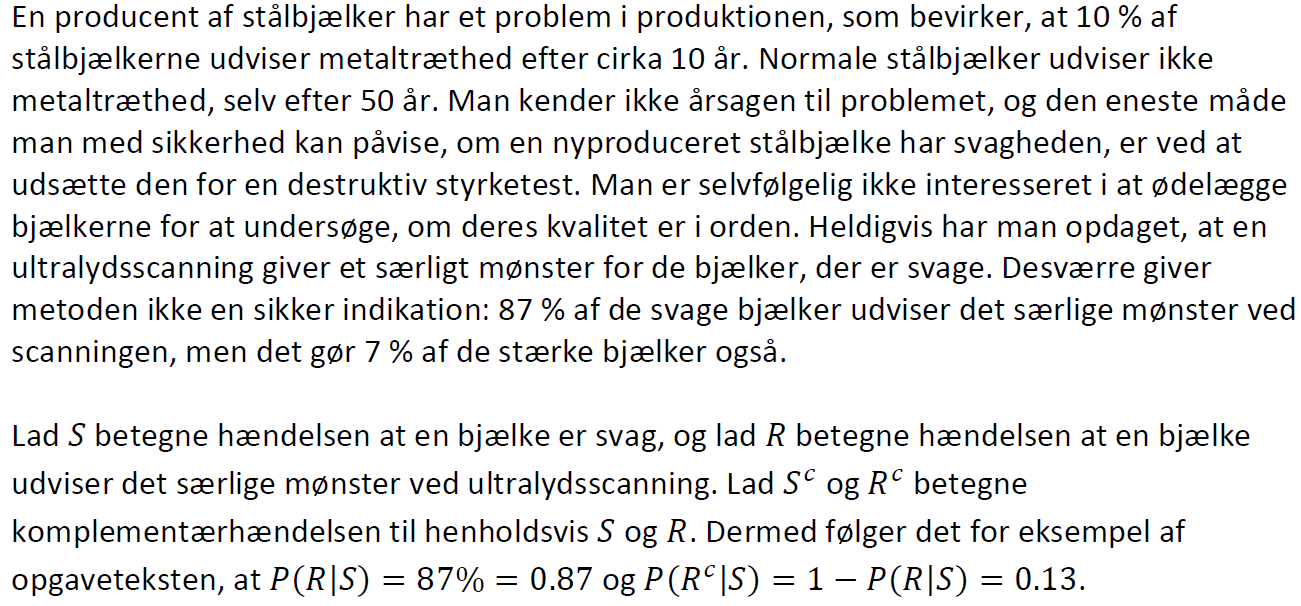

### a.

Sandsynligheden for at Det er en svag bjælke

clear
P_R_giv_S = 0.87

P_R_giv_S = 0.8700

P_S = 0.1 % 10%

P_S = 0.1000

Sand for at det ikke er en svag bjælke

P_Sc = 1 - P_S

P_Sc = 0.9000

Sand for særlighændelse givet de IKKE svage bjælker

P_R_giv_Sc = 0.07

P_R_giv_Sc = 0.0700

Sand for at IKKE særlighændelse givet IKKE svag

P_Rc_giv_Sc = 1 - P_R_giv_Sc

P_Rc_giv_Sc = 0.9300

P_R = 0.87 * P_S + 0.07 * P_Sc

P_R = 0.1500

P(S|R) = P(R|S)*P(S)/P(R) (Bayes)

P_S_giv_R = P_R_giv_S * P_S / P_R  % but why???

P_S_giv_R = 0.5800

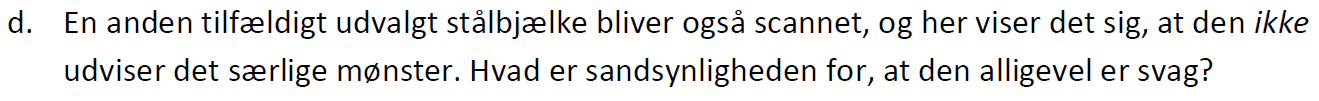

Tilfældig stålbjælke der IKKE har særligt mønster

P_S_giv_RC = (1 - P_R_giv_S) * P_S / (1 - P_R)

P_S_giv_RC = 0.0153

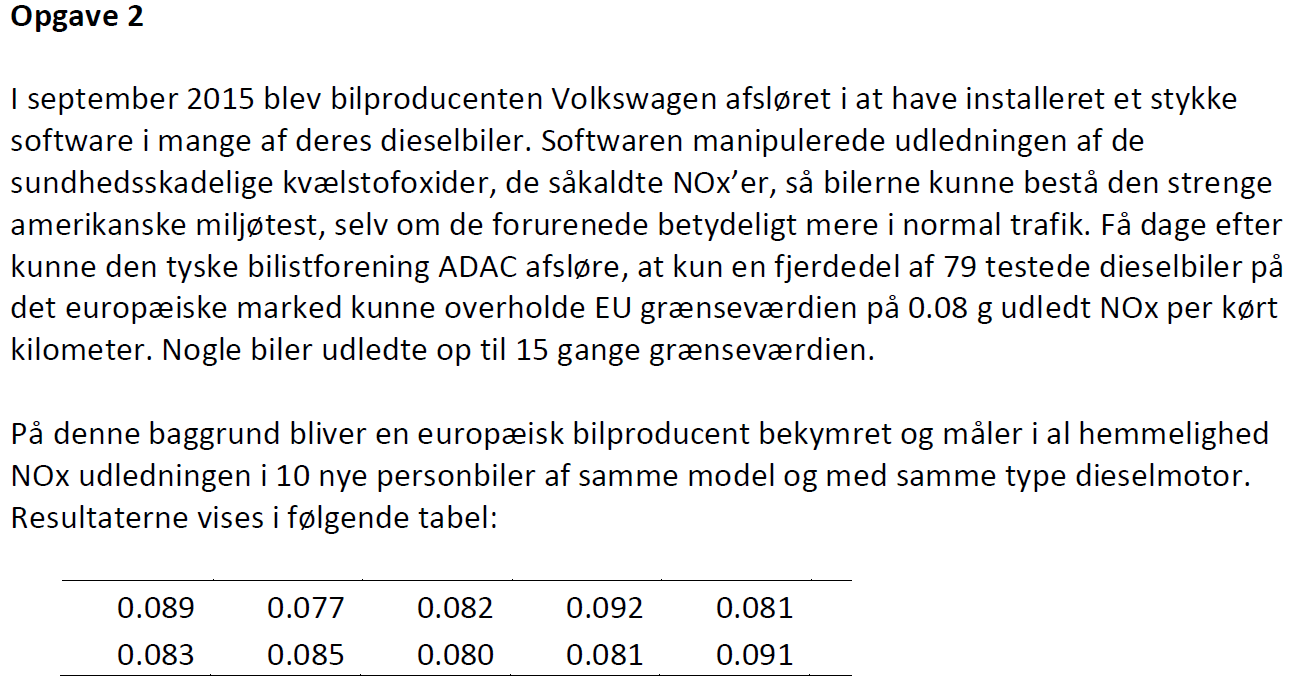

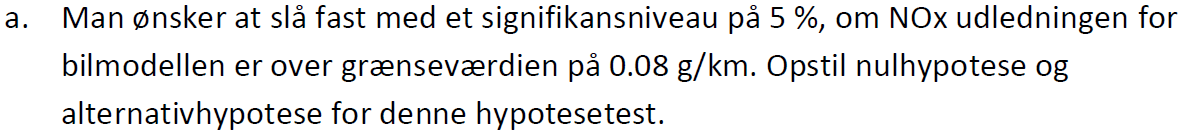

data = [0.089 0.077 0.082 0.092 0.081 0.083 0.085 0.081 0.091];
y = normpdf(data)

y =     0.3974    0.3978    0.3976    0.3973    0.3976    0.3976    0.3975    0.3976    0.3973


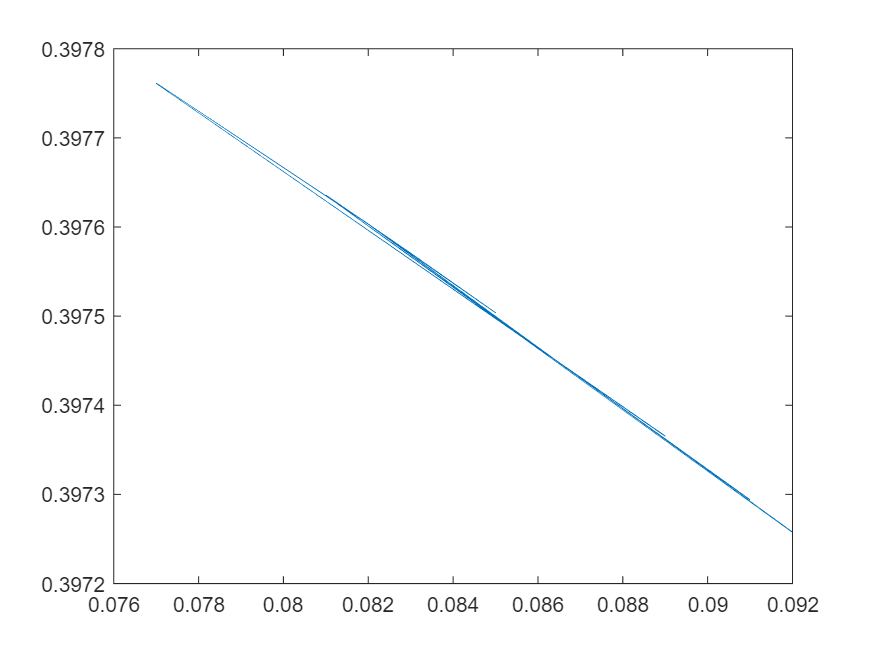

plot(data, y)

alpha = 0.05;

alpha = 0.0500

### b.

Opstil en formel for teststatistikken. Angiv hvilken fordeling den følger.

### c.

Beregn den kritiske region for testen, beregn teststatistikkens værdi og konkludér på hypotesetesten.

### d.

Beregn et 95 % konfidensinterval for den sande værdi af bilmodellens gennemsnitlige NOx udledning.

### e.

Beregn et 95 % prædiktionsinterval for den sande værdi af bilmodellens gennemsnitlige NOx udledning.

### f.

Oplys hvilke antagelser, der er gjort i hypotesetesten, og om antagelserne er rimelige på baggrund af data.

## Opgave 4

Danmarks Meteorologiske Institut (DMI) har indsamlet klimadata i Danmark siden 1768. En af DMI’s vigtigste beskæftigelser er dog at beregne vejrudsigten for de kommende dage. Selv om vejret er meget omskifteligt i Danmark, er det efterhånden blevet muligt for DMI at forudsige vejret ret præcist en uges tid frem i tiden, på grund af avancerede prognosemodeller og supercomputere. Mange danskere ønsker vejrudsigter længere ud i fremtiden end en uges tid, f.eks. en prognose for hvid jul eller for en varm sommer.

Du skal undersøge, om det er muligt at lave en god forudsigelse af temperaturen i højsommeren ud fra temperaturen i forsommeren.

I tabellen på næste side vises DMI’s årlige målte gennemsnitstemperaturer for forsommeren (maj og juni) og for højsommeren (juli og august), fra 1874 til 2014.

### a.

Lav en lineær regressionsanalyse af middeltemperaturen i højsommeren som funktion af middeltemperaturen i forsommeren og skriv regressionsligningen op.

clear, clf
data = xlsread("Eksamens sæt\15E\M4STI1_2015E_data.xlsx");
aarstal = data(:,7);
forsommer = data(:,8);
hojsommer = data(:,9);

Først plottes vores data så vi kan se hvad vi har med at gøre

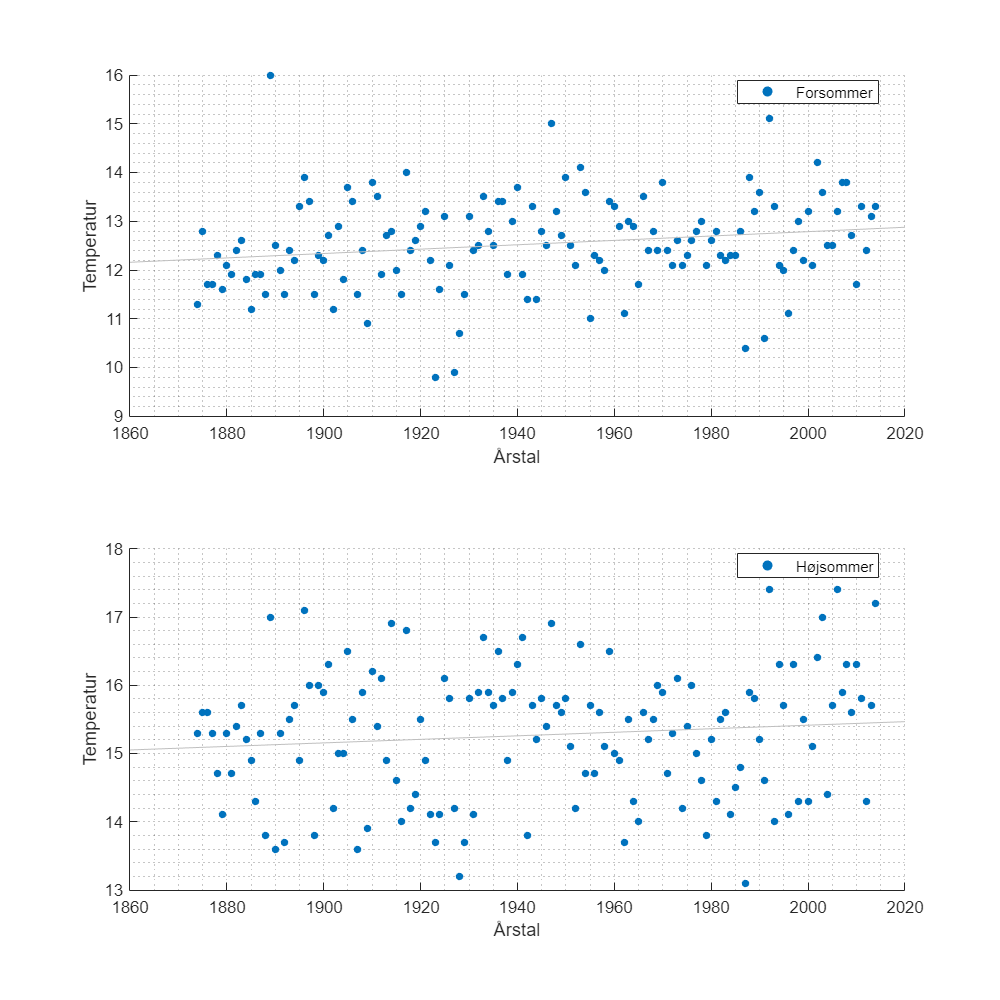

subplot(2,1,1)
subtitle('Klimaet i Danmark');
a = scatter(aarstal, forsommer, 20, 'filled', DisplayName='Forsommer');
lsline%(a, DisplayName='Forsommer')%(DisplayName='lsline forsommer');
% lsline;
xlabel('Årstal');
ylabel('Temperatur');
legend([a],Location="best")
grid('minor')

subplot(2,1,2)
b = scatter(aarstal, hojsommer, 20, 'filled', DisplayName='Højsommer');
ls_b = lsline;%(DisplayName='lsline højsommer');
xlabel('Årstal');
ylabel('Temperatur');
legend([b], Location="best")
grid('minor')

Vi opstiller ligningen


$$y = b_0 + b_1 \cdot x$$


mdl = fitlm(forsommer, hojsommer)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     7.2963       0.8232    8.8633    3.3397e-15
    x1             0.63605     0.065483    9.7133    2.4276e-17


Number of observations: 141, Error degrees of freedom: 139
Root Mean Squared Error: 0.737
R-squared: 0.404,  Adjusted R-Squared: 0.4
F-statistic vs. constant model: 94.3, p-value = 2.43e-17

Vi får nu $y = 7,2963 + 0,63605 \cdot x$

hvor 𝑥 er temperaturen i forsommeren og 𝑦 er den estimerede temperatur for højsommeren:

### b.

Forklar ved hjælp af regressionsanalysens statistikker, om modellen er god.

Vi ser, at både koefficienten for skæring og for hældningskoefficient er signifikant forskellige fra 0 (begge p-værdier er næsten 0). Der er altså en klar sammenhæng mellem temperaturen i forsommeren og i højsommeren. Der er dog meget usikkerhed i forudsigelserne, hvilket kommer til udtryk i, at R-squared og Adjusted R-Squared er temmelig lave, kun hhv. 0.404 og 0.4. Det vil sige, at modellen kun kan forudsige omkring 40 pct. af variabiliteten i data. Det er et udtryk for, at det er svært at lave vejrudsigter i Danmark, at vejret er meget uforudsigeligt.

### c.

Hvad er modellens forventede middeltemperatur for højsommeren 2015, hvor forsommeren var 11.25 grader i gennemsnit?

hojsommer_2015 = 7.2963 + 0.63605 * 11.25

hojsommer_2015 = 14.4519

Således vil temperaturen være 14,45 C

### d.

Lav en eller flere figurer, der illustrerer data og regressionsmodellen.

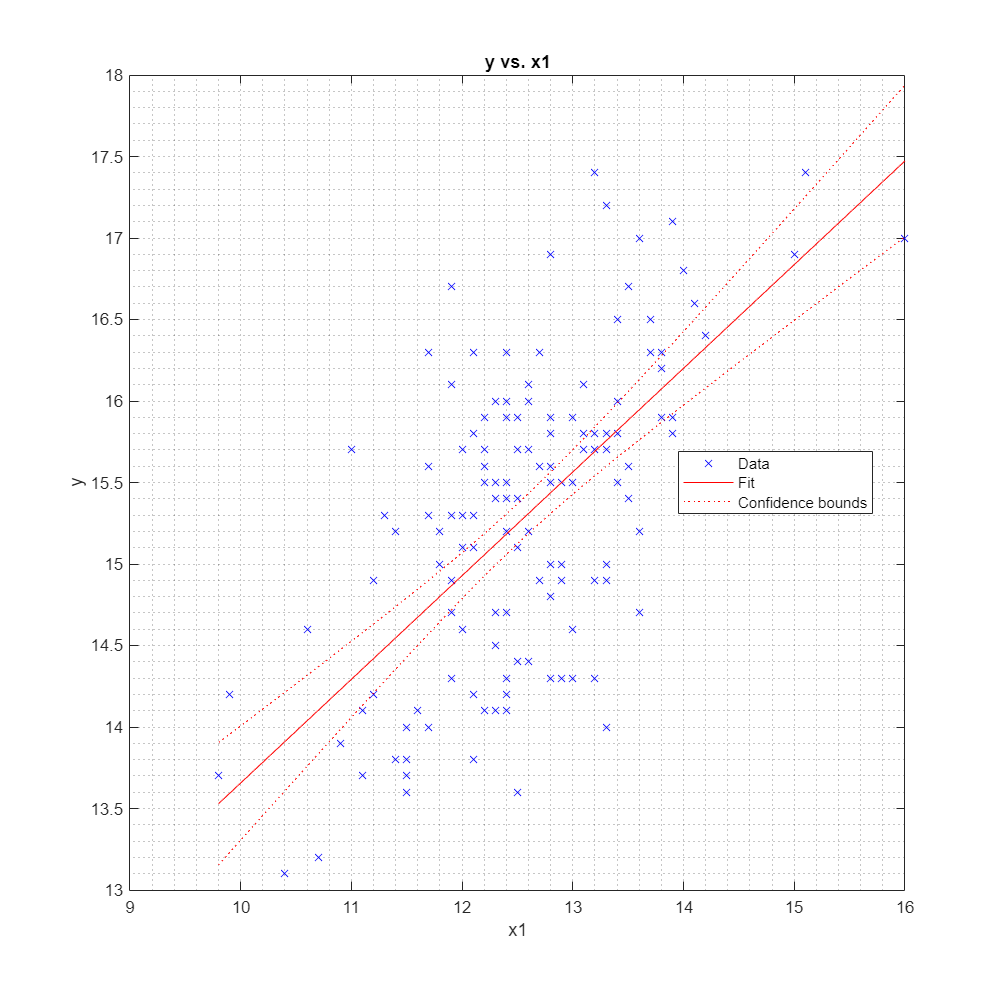

clf
plot(mdl)
grid('minor')

### e.

Lav en residualanalyse.

mdl = fitlm(forsommer, hojsommer); 
[yhat, yci] = predict(mdl,forsommer); % benyt de 3 x-værdier
estemat = yhat;
residual = forsommer - estemat;
KI_lav = yci(:,1);
KI_hoj = yci(:,2);

table(aarstal, forsommer, hojsommer, estemat, residual, KI_lav, KI_hoj)

ans = 141×7 table
    aarstal    forsommer    hojsommer    estemat    residual    KI_lav    KI_hoj
    _______    _________    _________    _______    ________    ______    ______

     1874        11.3         15.3       14.484     -3.1837     14.282    14.685
     1875        12.8         15.6       15.438     -2.6378      15.31    15.565
     1876        11.7         15.6       14.738     -3.0381     14.575    14.902
     1877        11.7         15.3       14.738     -3.0381     14.575    14.902
     1878        12.3         14.7        15.12     -2.8197     14.993    15.246
     1879        11.6         14.1       14.674     -3.0745     14.502    14.847
     1880        12.1         15.3       14.993     -2.8925     14.857    15.128
     1881     

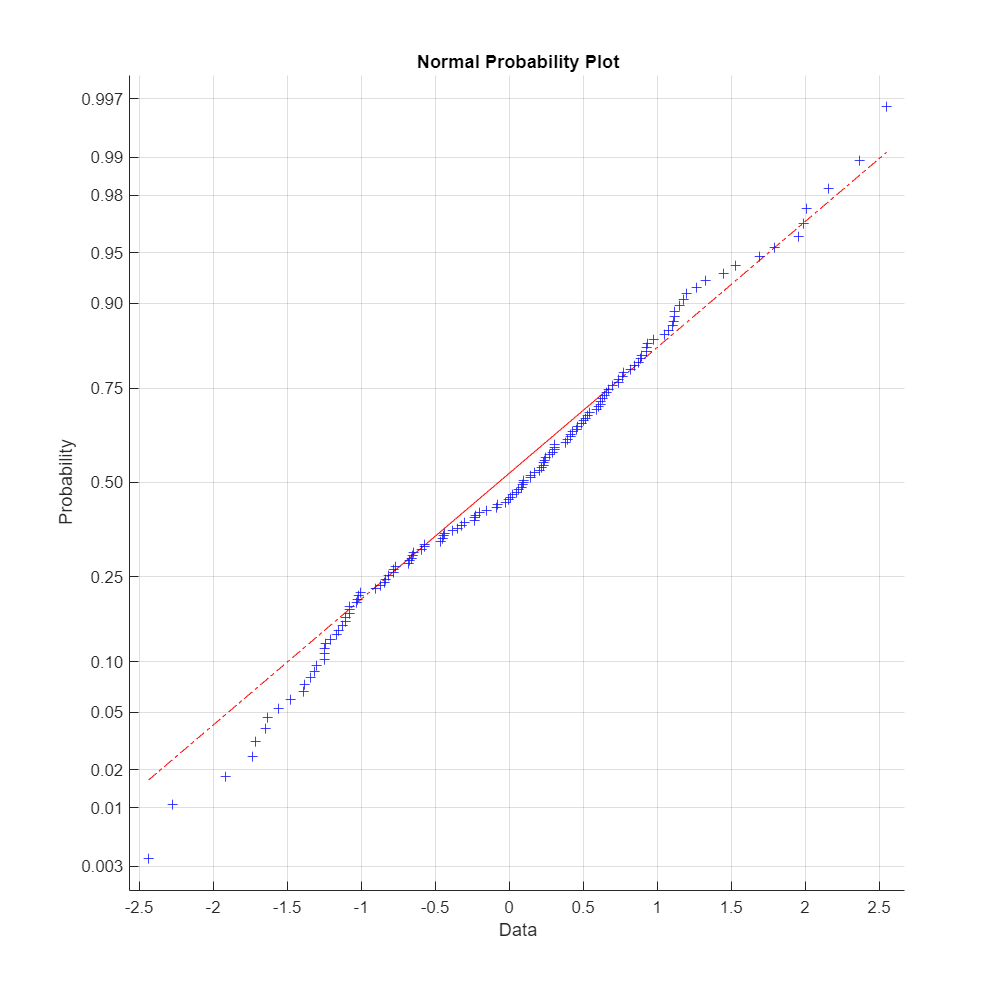

clf
% Residualerne skal gerne være normalfordelte. Det tester vi med et normalfordelingsplot

rst = mdl.Residuals.Studentized; % en anden måde at få residualerne på
normplot(rst)

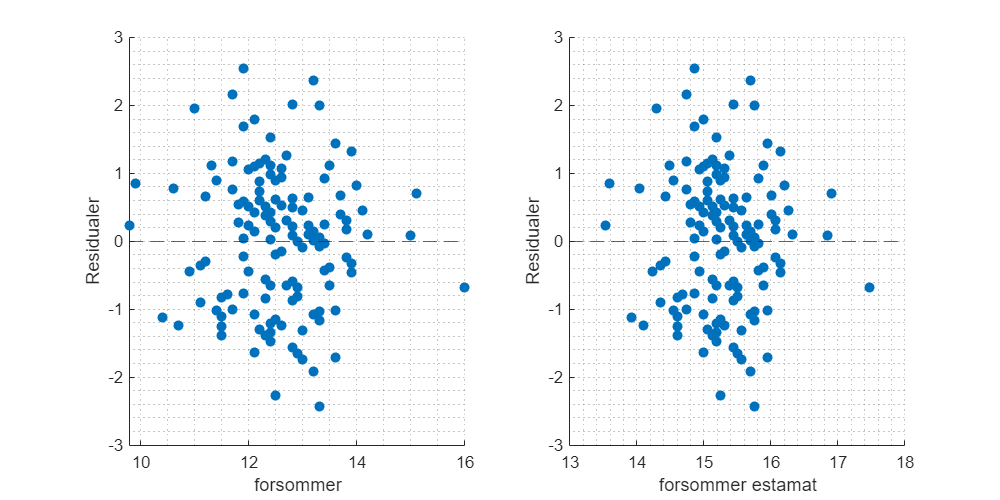



figure('Position', [0 0 800 400])
subplot(1,2,1)
scatter(forsommer, rst, 'filled') % , sygdom, bekym
yline(0, '--')
xlabel('forsommer')
ylabel('Residualer')
grid('minor')

subplot(1,2,2)
scatter(estemat, rst, 'filled') % , sygdom, bekym
yline(0, '--')
xlabel('forsommer estamat')
ylabel('Residualer')
grid('minor')

% subplot(2,2,3)
% scatter(hojsommer, rst, 'filled')
% yline(0, '--')
% xlabel('hojsommer')
% ylabel('Residualer')
% grid('minor')

For forsommeren ser residualplottet fint ud med tilfældig spredte residualer, for højsommeren ser vi en lineær stigning af risidualer hvilket tyder på en mindre god model.

% STAT.Residual(mdl, hojsommer')